# EEG脑机接口

## 数据导入

clear;clf;
%load common data
load("ChanName.mat");
load('Pair54.mat');
load('timeRawTrace.mat')
for i = 1:54
    Pair(i) = sprintf("Channel%d & %d",Pair54(i,1),Pair54(i,2));
end

%load personal data
for i = 1:4
    rawTracePerson = sprintf("Person%d\\Person%d\\rawTracePerson%d.mat",i,i,i);
    OSPerson = sprintf("Person%d\\Person%d\\OSPerson%d.mat",i,i,i);

    rawTracePerson_info = whos('-file', rawTracePerson);
    rawTracePerson_name = {rawTracePerson_info.name};
    OSPerson_info = whos('-file',OSPerson);
    OSPerson_name = {OSPerson_info.name};
    
    load(rawTracePerson);
    load(OSPerson);
    for j=1:length(rawTracePerson_name)
        eval(sprintf("%s_P%d = %s;",rawTracePerson_name{j},i,rawTracePerson_name{j}));
    end
  
    for j=1:length(OSPerson_name)
        eval(sprintf("%s_P%d = %s;",OSPerson_name{j},i,OSPerson_name{j}));
    end
    
end

## 观察原始数据

%rawTrace
fs = 300;
t = 0:1/fs:7-(1/fs);
numChannels = 19;
channelNames = [];
channelid = [1:8,10:16,19:20,23:24];

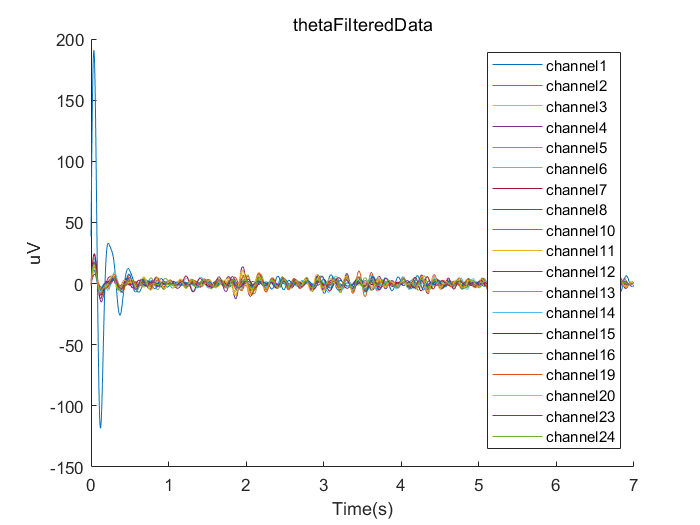

for i = 1:length(channelid)
    channelNames = [channelNames, sprintf("channel%d",channelid(i))];
end
colors = lines(numChannels);
thetaFreqRange = [4 8]; % Theta频带的频率范围（以赫兹为单位）
%bandpass filter
% 计算滤波器参数
filterOrder = 3; % 滤波器阶数
thetaWn = thetaFreqRange / (fs/2); % 归一化的频率范围
% 设计并应用带通滤波器
[b1, a1] = butter(filterOrder, thetaWn, 'bandpass'); % 设计Butterworth带通滤波器
figure;
hold on;
thetaFiltereddata = [];
for i = 1:numChannels
    thetaFilteredData = filtfilt(b1, a1, dataTrial_P1(:,2,i)); % 应用滤波器(零相位滤波）
    plot(t,thetaFilteredData, 'color', colors(i, :));
    thetaFiltereddata = horzcat(thetaFiltereddata,thetaFilteredData);
end
hold off;
legend(channelNames);
title('thetaFilteredData');
xlabel('Time(s)');
ylabel('uV');

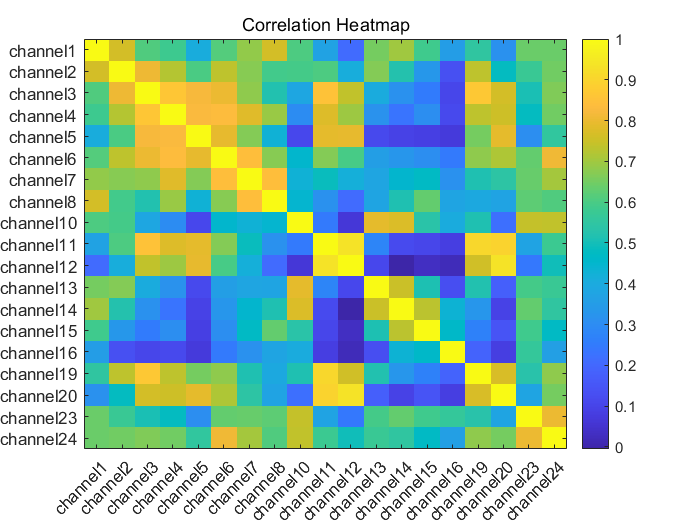

correlationMatrix = corrcoef(thetaFiltereddata);
figure;
imagesc(correlationMatrix);
colorbar; % 添加颜色刻度条
title('Correlation Heatmap'); % 添加标题
xticks(1:numChannels);
yticks(1:numChannels);
xticklabels(channelNames);
yticklabels(channelNames);
xtickangle(45);

## SVM rbf核 分类

### 单人、各组通道配对、全时频点

% 定义范围
lowerBound = 4;
upperBound = 8;
thetaindex = find(fOS_P1>=lowerBound & fOS_P1<= upperBound);
% 使用逻辑索引提取满足条件的数据
thetaOS_P1 = OS_P1(:,thetaindex,:,:);
%将Track替换为match/nonmatch(1/0)
isMatch = (Track_P1<11)';
%PLV值特征提取：
%一、全视频点
%1：全时频点求常见统计量：平均值、方差、最大值、中值
for j = 1:54
    for i = 1:40
        plv = thetaOS_P1(:,:,i,j);
        % 计算平均值
        mean_plv(i) = mean(plv(:));
        
        % 计算方差
        var_plv(i) = var(plv(:));
        
        % 计算最大值
        max_plv(i) = max(plv(:));
        
        % 计算中值
        median_plv(i) = median(plv(:));
        
        % 计算平均值
        %mean_plv(i) = mean(thetaOS_P1(:,:,i,5),"all");
        % 计算方差
        %var_plv(i) = var(thetaOS_P1(:,:,i,5),"includenan");
        %column_variance = var(thetaOS(:,:,i,5));
        %row_variance = var(thetaOS(:,:,i,5), [], 2);
        % 计算最大值
        %max_plv(i) = max(thetaOS_P1(:,:,i,5), [], 'all');
        % 计算中值
        %median_plv(i) = median(thetaOS_P1(:,:,i,5),"all");
    end
    featurematrix = horzcat(mean_plv',var_plv',max_plv',median_plv');
    % 随机划分训练集和测试集
    rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(featurematrix, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = featurematrix(cv.training,:);
    y_train = isMatch(cv.training,:);
    X_test = featurematrix(cv.test,:);
    y_test = isMatch(cv.test,:);
    
    % 使用 SVM 建模并进行训练
    svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'rbf');
    
    % 在测试集上进行预测
    y_pred = predict(svmModel, X_test);
    
    % 评估预测结果
    accuracy_stat(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end


%2：全时频点奇异值分解
k = 1; % 选择前 k 个奇异值
features = zeros(40, k); % 存储提取的特征
for j = 1:54
    for i = 1:40
        plv = thetaOS_P1(:,:,i,j);
        [U, S, V] = svd(plv);
        features(i,:) = diag(S(1:k, 1:k))';
    end
    % 随机划分训练集和测试集
    rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(features, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = features(cv.training,:);
    y_train = isMatch(cv.training,:);
    X_test = features(cv.test,:);
    y_test = isMatch(cv.test,:);
    % 使用 SVM 建模并进行训练
    svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'rbf');
    
    % 在测试集上进行预测
    y_pred = predict(svmModel, X_test);
    
    % 评估预测结果
    accuracy_svd(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end

%全时频点PCA
k = 1; % 选择前 k 个主成分
features = zeros(40, k); % 存储提取的特征
[m,n] = size(thetaOS_P1(:,:,1,5));
for j = 1:54
    dataVector = reshape(thetaOS_P1(:,:,:,j), m*n, 40)';
    [coeff, score, ~, ~, explained] = pca(dataVector);
    features = score(:, 1:k);
    % 随机划分训练集和测试集
    rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(features, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = features(cv.training,:);
    y_train = isMatch(cv.training,:);
    X_test = features(cv.test,:);
    y_test = isMatch(cv.test,:);
    % 使用 SVM 建模并进行训练
    svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'rbf');
    
    % 在测试集上进行预测
    y_pred = predict(svmModel, X_test);
    
    % 评估预测结果
    accuracy_pca(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end

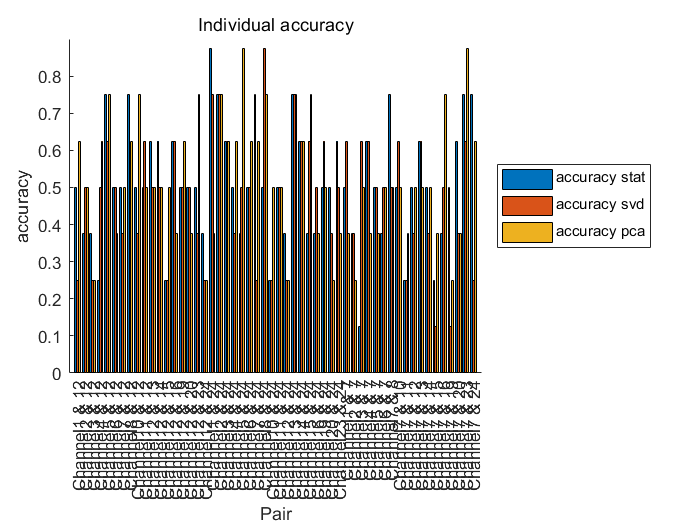

x = 1:54;
% 设置每个柱形的宽度和间隔
barWidth = 0.25;
barSpacing = 0;

% 计算每组数据的偏移位置以使其不重叠显示
offset1 = -(barWidth + barSpacing);
offset2 = 0;
offset3 = barWidth + barSpacing;

% 绘制柱状图
figure;
hold on;
bar(x + offset1, accuracy_stat, barWidth)
bar(x + offset2, accuracy_svd, barWidth)
bar(x + offset3, accuracy_pca, barWidth)
hold off;
title("Individual accuracy");
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);
legend(["accuracy_ stat","accuracy_ svd","accuracy_ pca"],'Location', 'eastoutside');